# MTH305 Risk Management

# Assessment #002 AI-assisted role-play project - PART ONE

# 2026-27

## Group ID: A2-G52

Module Learning Outcomes (LOs)

Instructions

- Part One is worth 50 marks in total.

- This file is the MATLAB template file for you to conduct programming for the coursework.

- Variable names and sizes (e.g., T-by-1) wherever given in this template file must not be changed or deleted.

- You must use the given variables to represent the quantities required.

- You are allowed to create new variables.

- User-defined functions are not permitted. The only exception is the provided VaR_count and import_data functions.

- Sample variance and covariance refers to the variance and covariance of the full sample normalized by (number of observations - 1).

- To count the number of words, you may copy the text into a Word file, and the word count will appear at the bottom left corner.

- The quality of the MATLAB code will not be marked.

Context

- Suppose you are a Market Risk Analyst at a bank and report to the Vice President (VP) in Market Risk.

- It is now at the end of day 20250930.

- You are reviewing a portfolio of stocks.

- The portfolio consists of 30 stocks, with 10 million Chinese Yuan (CNY) invested in each stock. [All calculated numbers are in million yuan.]

- You would calculate the 1-day 99% value at risk (VaR) of the portfolio.

- Your job is to assess if there is an appropriate amount of capital placed for this investment.

Data

- The data is the daily closing price of stocks traded on Shanghai and Shenzhen Stock Exchanges in the sample period from 20231009 to 20250930, downloaded from China Stock Market & Accounting Research (CSMAR).

To run the code, the following files must be in the Files or Current Folder of MATLAB.

- MTH305_A2_Part1_Script.mlx

- MTH305_A2_Part1_Data.mat

- import_data.m

clear
clc

% VaR parameters
confidence = 0.99;   % confidence level

## 1. Import data

Each group is randomly assigned 30 stocks for the analysis.

Replace 100 with your own group ID. Failure to use your group's correct ID will result in a **10-mark deduction** and may also trigger an investigation into possible collusion.

my_group_id = 53 

my_group_id = 53

[stock_price, stock_id, stock_date] = import_data(my_group_id);

## 2. VaRs of the stock position

**Q1 [LO-A].** Explain, in your own words, the theory and methodology underlying the historical simulation and model-building approaches, including the variations presented in Sections 2.1-2.5. Your answer should discuss their key concepts, assumptions, and main differences, without describing the calculation procedures step by step or using equations. **(15 marks)**

[Word limit: 300]

[Word count: XXX]

**Q2 [LO-CE].** Calculate five measures of VaR. **(25 marks)**

For each mistake, 5 marks will be deducted, down to a minimum of 0.

Notations for days

- Day(0): 20231009

- Day(1): 20231010

- today: 20250930

The variables for the stock portfolio are given below.

[stock_price]: T-by-N_stock, stock close price -- please do not change the order of stocks

[cny_invest]: N_stock-by-1, amount in CNY invested in each stock

[V_stock]: scalar, current value of the stock portfolio

[weight_stock]: N_stock-by-1, weight of each stock in the portfolio of stocks

[T, N_stock] = size(stock_price);
cny_invest = ones(N_stock, 1) *10;   % 10 million yuan
V_stock = sum(cny_invest);
weight_stock = cny_invest / V_stock;

Compute the following variables.

[return_stock]: (T-1)-by-N_stock, stock return, simple (not log) return, where 1st row is return on Day(1)

[return_portfolio]: (T-1)-by-1, portfolio return, where 1st row is return on Day(1)

% Put your code here and replace the random number (randn).

% disp(N_stock)
% disp(T)

return_stock = zeros(T-1, N_stock);
for j = 1:N_stock
    for i = 2:T
        return_stock(i-1, j) = (stock_price(i,j) - stock_price(i-1,j)) / stock_price(i-1,j);
    end
end

return_portfolio = zeros(T-1, 1);
for i = 1:(T-1)
    sum_returns = 0;
    for j = 1:N_stock
        sum_returns = sum_returns + return_stock(i,j) * weight_stock(j);
    end
    return_portfolio(i) = sum_returns;
end

% for i = 1:(T-1)
%     fprintf('%.4f\n',return_portfolio(i));
% end


### 2.1 historical simulation, equal weight

Compute the following variables.

[loss1]: (T-1)-by-1, portfolio loss for (T-1) scenarios

[weight1]: (T-1)-by-1, corresponding weight of loss

[VaR1]: scalar, calculated by calling the function VaR_count in Week 5's lab

% change to your own path that contains VaR_count.m in Week 5's lab
% addpath(genpath('../../../slides/W5 historical simulation/lab'))
N_scenarios = T-1;
% Put your code here and replace the random number (randn).
loss1 = -(V_stock * return_portfolio);
weight1 = ones(N_scenarios, 1) * (1/N_scenarios);
VaR1 = VaR_count(loss1, weight1, confidence);
fprintf('VaR1 = %.2f\n', VaR1)

VaR1 = 18.52


### 2.2 historical simulation, exponential weight

Compute the following variables.

[loss2]: (T-1)-by-1, portfolio loss for (T-1) scenarios

[weight2]: (T-1)-by-1, corresponding weight of loss with recent data having more weight

[VaR2]: scalar, calculated by calling the function VaR_count in Week 5's lab

lambda = 0.94;

% Put your code here and replace the random number (randn).
weight2 = NaN(N_scenarios, 1);
loss2 = loss1;
for i = 1 : N_scenarios
    weight2(i) = lambda^(N_scenarios-i) *(1-lambda) / (1-lambda^N_scenarios);
end
VaR2 = VaR_count(loss2, weight2, confidence);

fprintf('VaR2 = %.2f\n', VaR2)

VaR2 = 8.67


### 2.3 historical simulation, volatility scaling

#### 2.3.1 estimate GARCH(1,1) model for the volatility of portfolio returns


$$\sigma_n^2=\omega +\alpha u_{n-1}^2+\beta\sigma_{n-1}^2.$$


Let the module leader know if there is a warning when calling the function below.

Mdl = garch(1, 1);
EstMdl = estimate(Mdl, return_portfolio);

 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00011428     1.7103e-05        6.6816      2.3631e-11
    GARCH{1}       0.35101       0.080764        4.3461      1.3859e-05
    ARCH{1}         0.3324       0.057967        5.7343      9.7921e-09



Read parameter estimates from 'EstMdl'.

[omega_hat, beta_hat, alpha_hat]: estimates of model parameters

% Put your code here and replace the random number (randn).
omega_hat = EstMdl.Constant;
beta_hat = EstMdl.GARCH{1,1};
alpha_hat = EstMdl.ARCH{1,1};

#### 2.3.2 calculate model-implied variances

Compute the following variable.

[var_hat]: (T-1)-by-1, time series of model-implied variances

- var_hat(i) in row i is the estimated variance of portfolio return on Day(i) using information up to Day(i-1)

- var_hat(1) = NaN

- var_hat(2) = u(1)^2

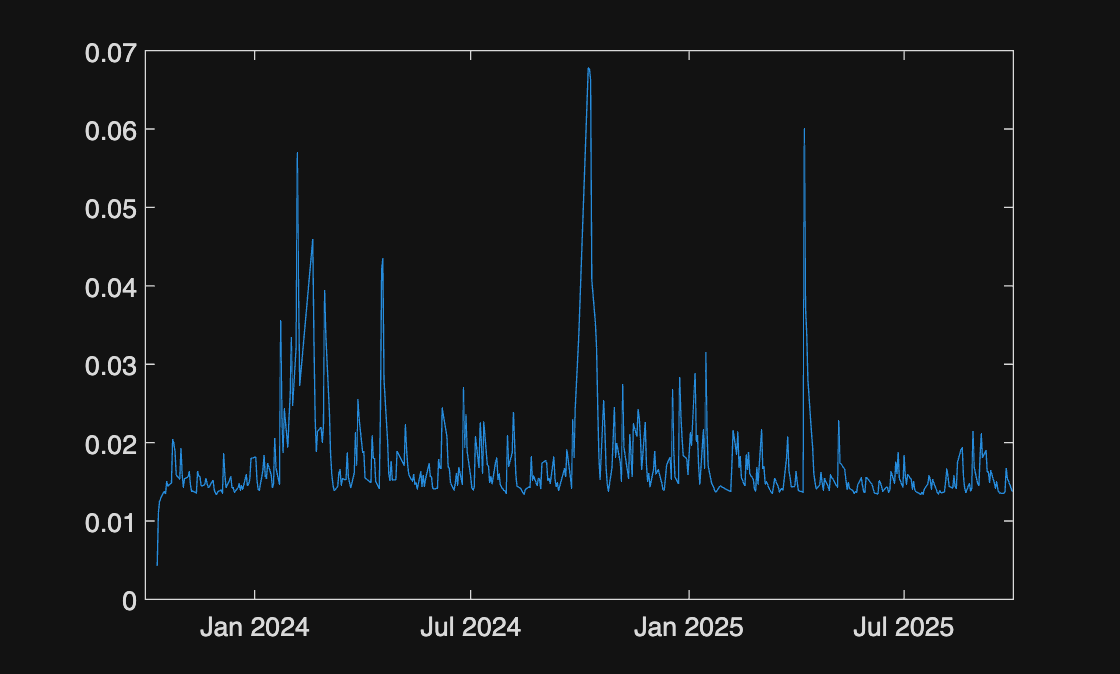

% Put your code here and replace the random number (randn).
var_hat = NaN(T-1,1);
var_hat(2) = return_portfolio(1)^2;
for i = 3:(T-1)
    var_hat(i) = omega_hat + alpha_hat * (return_portfolio(i-1)^2) + beta_hat*(var_hat(i-1));
end

plot(stock_date(2:end), sqrt(var_hat))

#### 2.3.3 calculate the variance of the return on the next trading day

Compute the following variable.

[variance_ntd]: scalar, variance of the return on the next trading day

% Put your code here and replace the random number (randn).
variance_ntd = omega_hat + alpha_hat * (return_portfolio(T-1)^2) + beta_hat*var_hat(T-1)

variance_ntd = 1.9172e-04

#### 2.3.4 calculate volatility-scaled VaR

Compute the following variable.

[VaR3]: scalar, calculated by calling the function VaR_count in Week 5's lab

% Put your code here and replace the random number (randn).


% THIS !! verify

loss3 = ones(T-1,1);
for i = 2:(T-1)
    loss3(i) = -(V_stock * (return_portfolio(i) * sqrt(variance_ntd/var_hat(i))));
end
weight3 = weight2;
VaR3 = VaR_count(loss3, weight3, confidence);
fprintf('VaR3 = %.2f\n', VaR3)

VaR3 = 8.53


### 2.4 model-building approach, variance-covariance matrix equal weight

Compute the following variables.

[varcov]: N_stock-by-N_stock, sample variance-covariance matrix of returns

[var_portfolio]: scalar, variance of change in the portfolio value

[VaR4]: scalar, VaR

% Put your code here and replace the random number (randn).
n = T-1;
varcov = cov(return_stock); %ews
delta = cny_invest;
var_portfolio = delta' * varcov * delta;
VaR4 = -norminv(1 - confidence) * sqrt(var_portfolio); 
fprintf('VaR4 = %.2f\n', VaR4)

VaR4 = 13.27


### 2.5 model-building approach, variance-covariance matrix EWMA

Compute the following variables.

[varcov_day1]: N_stock-by-N_stock, variance-covariance matrix of returns on Day(1)

- set equal to the sample variance-covariance matrix of returns

[varcov_ntd]: N_stock-by-N_stock, variance-covariance matrix of returns on the next trading day

[VaR5]: scalar, VaR

lambda = 0.94;

varcov_day1 = cov(return_stock); 
varcov_ntd = varcov_day1;


for i = 1:(T-1)
    r_i = return_stock(i, :)'; 
    varcov_ntd = lambda * varcov_ntd + (1 - lambda) * (r_i * r_i');
end

var_portfolio = delta' * varcov_ntd * delta;
VaR5 = -norminv(1 - confidence) * sqrt(var_portfolio);

fprintf('VaR5 = %.2f\n', VaR5)

VaR5 = 7.28


## 3. Report to the VP

**Q3 [LO-BD].** Suppose the bank currently allocates CNY 10 million in capital to this portfolio. Write a concise professional report to the VP explaining your calculation results and assessing whether the allocated capital is appropriate. In particular, discuss how differences in volatility contribute to variations in the VaR estimates. Write for a senior management audience. Use clear, precise language, focus on decision-relevant information, and avoid unnecessary technical detail. **(10 marks)**

The content itself will not be graded. You will receive full marks if your response is relevant and between 150 and 200 words; otherwise, you will receive zero marks.

The use of AI is not allowed.

[Word count: XXX]

## 4. Learning Mall Submission

Please export this file as a PDF (LIVE EDITOR -> Export to PDF), and submit the exported PDF to Learning Mall.